# **Soil-structure interaction: 2d Portal Frame**

This example originates from the GitHub repository maintained by Professor Quan Gu of Xiamen University:

[OpenSeesXMU/A-practical-guide-to-OpenSees---examples](https://github.com/OpenSeesXMU/A-practical-guide-to-OpenSees---examples/tree/master)

clear; clc;

opsm = OpenSeesMatlab();
ops = opsm.opensees;

### Model

%% ------------------------------------------------------------------------
%  Xiamen University example
%  Soil-structure interaction analysis of a two-story frame on foundation soil
%
%  Original unit system:
%    length : m
%    mass   : ton
%    time   : sec
%    force  : kN
%    stress : kPa
%
%  Notes
%  -----
%  Soil nodes use ndf = 2 (no rotational DOF), while frame nodes use ndf = 3.
%  Therefore, they must be modeled separately.
%
%  In this example, coincident frame and soil nodes are tied by equalDOF.
%  Relative slip at the interface is neglected for simplicity.
%
%  The original Tcl file uses quadWithSensitivity, which is treated here
%  as a quad-type plane strain soil element with the same arguments.
%% ------------------------------------------------------------------------

ops.wipe();

%% ------------------------------------------------------------------------
% Frame model (2D, 3 DOF per node)
%% ------------------------------------------------------------------------
ops.model('basic', '-ndm', 2, '-ndf', 3);

% Lumped masses of frame nodes
framemass1 = 15.0;
framemass2 = 30.0;
framemass3 = 4.0;

%% ------------------------------------------------------------------------
% Define frame nodes
% Node format:
%   node(tag, x, y)
%   mass(tag, mx, my, mrz)
%% ------------------------------------------------------------------------
ops.node(1,   0.0,  0.0);   ops.mass(1,  framemass1, framemass1, 0.0);
ops.node(2,   0.0,  3.6);   ops.mass(2,  framemass1, framemass1, 0.0);
ops.node(3,   0.0,  7.2);   ops.mass(3,  framemass1, framemass1, 0.0);

ops.node(4,   7.0,  0.0);   ops.mass(4,  framemass2, framemass2, 0.0);
ops.node(5,   7.0,  3.6);   ops.mass(5,  framemass2, framemass2, 0.0);
ops.node(6,   7.0,  7.2);   ops.mass(6,  framemass2, framemass2, 0.0);

ops.node(7,  14.0,  0.0);   ops.mass(7,  framemass1, framemass1, 0.0);
ops.node(8,  14.0,  3.6);   ops.mass(8,  framemass1, framemass1, 0.0);
ops.node(9,  14.0,  7.2);   ops.mass(9,  framemass1, framemass1, 0.0);

ops.node(10,  0.0, -2.4);   ops.mass(10, framemass3, framemass3, 0.0);
ops.node(11,  0.0, -1.2);   ops.mass(11, framemass3, framemass3, 0.0);
ops.node(12,  7.0, -2.4);   ops.mass(12, framemass3, framemass3, 0.0);
ops.node(13,  7.0, -1.2);   ops.mass(13, framemass3, framemass3, 0.0);
ops.node(14, 14.0, -2.4);   ops.mass(14, framemass3, framemass3, 0.0);
ops.node(15, 14.0, -1.2);   ops.mass(15, framemass3, framemass3, 0.0);

%% ------------------------------------------------------------------------
% Record frame nodal responses
%% ------------------------------------------------------------------------
% ops.recorder('Node', '-file', 'disp6.out', '-time', '-node', 6, '-dof', 1, 2, 'disp');
% ops.recorder('Node', '-file', 'disp5.out', '-time', '-node', 5, '-dof', 1, 2, 'disp');
% ops.recorder('Node', '-file', 'disp4.out', '-time', '-node', 4, '-dof', 1, 2, 'disp');

%% ------------------------------------------------------------------------
% Gravity loads on frame nodes
%% ------------------------------------------------------------------------
upperload1 = -framemass1 * 10.0;
upperload2 = -framemass2 * 10.0;
download3  = -framemass3 * 10.0;

ops.timeSeries('Constant', 2);
ops.pattern('Plain', 2, 2);

ops.load(1,  0.0, upperload1, 0.0);
ops.load(2,  0.0, upperload1, 0.0);
ops.load(3,  0.0, upperload1, 0.0);
ops.load(4,  0.0, upperload2, 0.0);
ops.load(5,  0.0, upperload2, 0.0);
ops.load(6,  0.0, upperload2, 0.0);
ops.load(7,  0.0, upperload1, 0.0);
ops.load(8,  0.0, upperload1, 0.0);
ops.load(9,  0.0, upperload1, 0.0);

ops.load(10, 0.0, download3, 0.0);
ops.load(11, 0.0, download3, 0.0);
ops.load(12, 0.0, download3, 0.0);
ops.load(13, 0.0, download3, 0.0);
ops.load(14, 0.0, download3, 0.0);
ops.load(15, 0.0, download3, 0.0);

%% ------------------------------------------------------------------------
% Materials for upper frame
%% ------------------------------------------------------------------------
% Cover concrete
ops.uniaxialMaterial('Concrete01', 1, -27588.5, -0.002, 0.0, -0.008);

% Core concrete
ops.uniaxialMaterial('Concrete01', 2, -34485.6, -0.004, -20691.4, -0.014);

% Reinforcement steel
% Hardening material:
%   tag, E, sigmaY, Hiso, Hkin
ops.uniaxialMaterial('Hardening', 3, 2.0e8, 248200.0, 0.0, 1.6129e6);

%% ------------------------------------------------------------------------
% Materials for lower foundation frame
%% ------------------------------------------------------------------------
ops.uniaxialMaterial('Concrete01', 4, -27588.5, -0.002, 0.0, -0.008);
ops.uniaxialMaterial('Concrete01', 5, -34485.6, -0.004, -20691.4, -0.014);
ops.uniaxialMaterial('Hardening', 6, 2.0e8, 248200.0, 0.0, 1.6129e6);

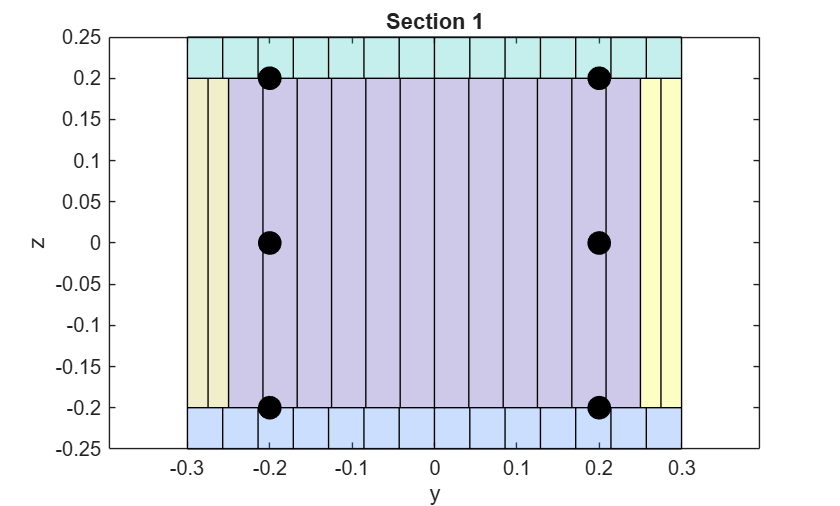

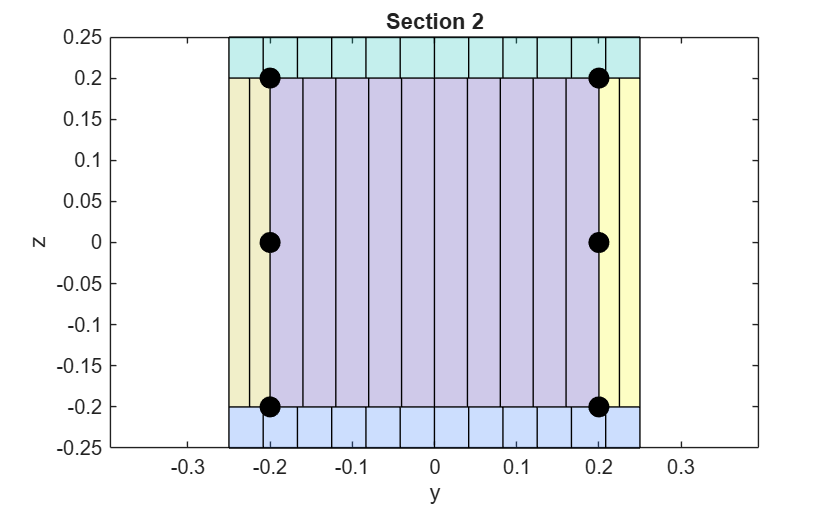

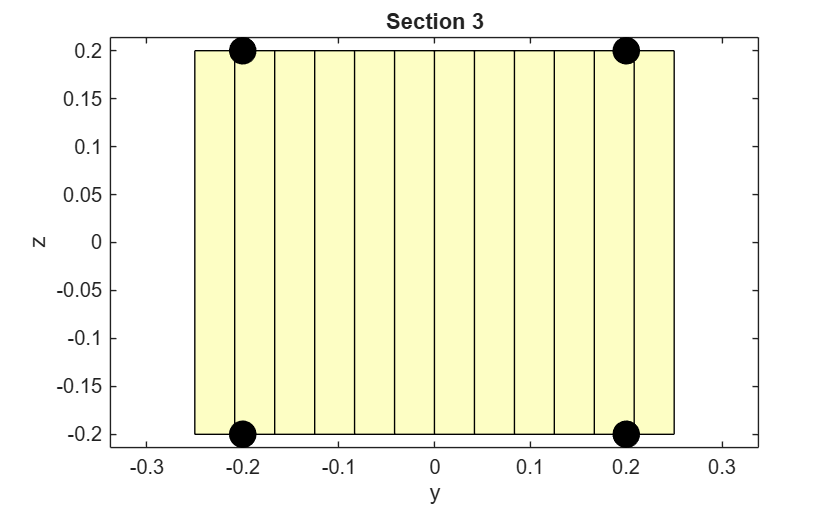

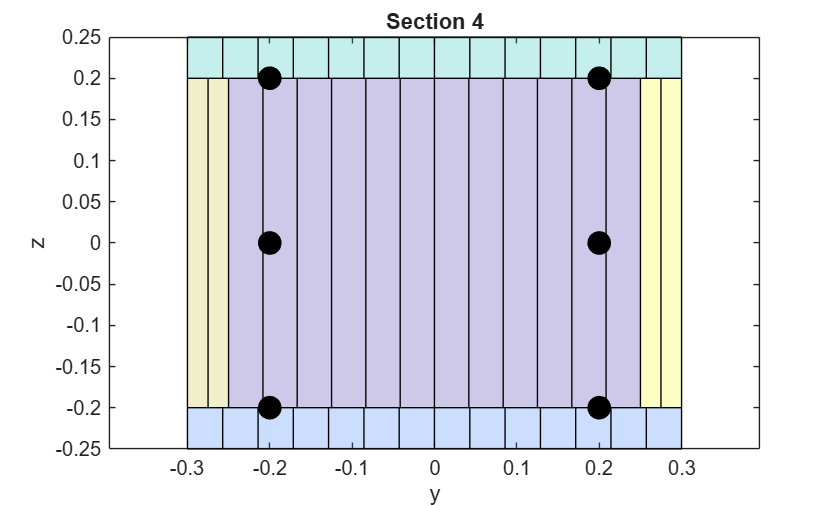

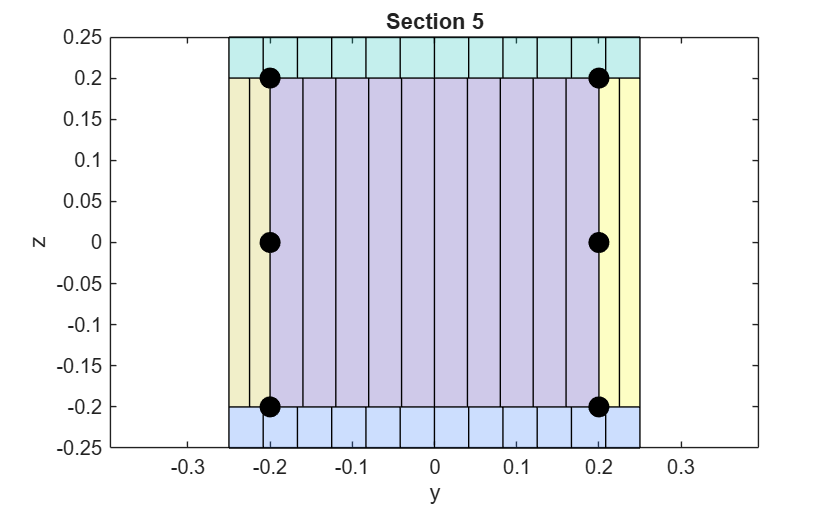


%% ------------------------------------------------------------------------
% Fiber sections for upper frame
%% ------------------------------------------------------------------------
opsm.pre.setSectionGeometryRecorder(true)
% Interior column section
ops.section('Fiber', 1);
ops.patch('quad', 2, 1, 12, -0.2500,  0.2000, -0.2500, -0.2000,  0.2500, -0.2000,  0.2500,  0.2000);
ops.patch('quad', 1, 1, 14, -0.3000, -0.2000, -0.3000, -0.2500,  0.3000, -0.2500,  0.3000, -0.2000);
ops.patch('quad', 1, 1, 14, -0.3000,  0.2500, -0.3000,  0.2000,  0.3000,  0.2000,  0.3000,  0.2500);
ops.patch('quad', 1, 1,  2, -0.3000,  0.2000, -0.3000, -0.2000, -0.2500, -0.2000, -0.2500,  0.2000);
ops.patch('quad', 1, 1,  2,  0.2500,  0.2000,  0.2500, -0.2000,  0.3000, -0.2000,  0.3000,  0.2000);
ops.layer('straight', 3, 3, 0.000645, -0.2000, 0.2000, -0.2000, -0.2000);
ops.layer('straight', 3, 3, 0.000645,  0.2000, 0.2000,  0.2000, -0.2000);

% Exterior column section
ops.section('Fiber', 2);
ops.patch('quad', 2, 1, 10, -0.2000,  0.2000, -0.2000, -0.2000,  0.2000, -0.2000,  0.2000,  0.2000);
ops.patch('quad', 1, 1, 12, -0.2500, -0.2000, -0.2500, -0.2500,  0.2500, -0.2500,  0.2500, -0.2000);
ops.patch('quad', 1, 1, 12, -0.2500,  0.2500, -0.2500,  0.2000,  0.2500,  0.2000,  0.2500,  0.2500);
ops.patch('quad', 1, 1,  2, -0.2500,  0.2000, -0.2500, -0.2000, -0.2000, -0.2000, -0.2000,  0.2000);
ops.patch('quad', 1, 1,  2,  0.2000,  0.2000,  0.2000, -0.2000,  0.2500, -0.2000,  0.2500,  0.2000);
ops.layer('straight', 3, 3, 0.00051, -0.2000, 0.2000, -0.2000, -0.2000);
ops.layer('straight', 3, 3, 0.00051,  0.2000, 0.2000,  0.2000, -0.2000);

% Beam section
ops.section('Fiber', 3);
ops.patch('quad', 1, 1, 12, -0.2500, 0.2000, -0.2500, -0.2000, 0.2500, -0.2000, 0.2500, 0.2000);
ops.layer('straight', 3, 2, 0.000645, -0.2000, 0.2000, -0.2000, -0.2000);
ops.layer('straight', 3, 2, 0.000645,  0.2000, 0.2000,  0.2000, -0.2000);

%% ------------------------------------------------------------------------
% Fiber sections for lower foundation members
%% ------------------------------------------------------------------------

% Interior foundation column section
ops.section('Fiber', 4);
ops.patch('quad', 5, 1, 12, -0.2500,  0.2000, -0.2500, -0.2000,  0.2500, -0.2000,  0.2500,  0.2000);
ops.patch('quad', 4, 1, 14, -0.3000, -0.2000, -0.3000, -0.2500,  0.3000, -0.2500,  0.3000, -0.2000);
ops.patch('quad', 4, 1, 14, -0.3000,  0.2500, -0.3000,  0.2000,  0.3000,  0.2000,  0.3000,  0.2500);
ops.patch('quad', 4, 1,  2, -0.3000,  0.2000, -0.3000, -0.2000, -0.2500, -0.2000, -0.2500,  0.2000);
ops.patch('quad', 4, 1,  2,  0.2500,  0.2000,  0.2500, -0.2000,  0.3000, -0.2000,  0.3000,  0.2000);
ops.layer('straight', 6, 3, 0.000645, -0.2000, 0.2000, -0.2000, -0.2000);
ops.layer('straight', 6, 3, 0.000645,  0.2000, 0.2000,  0.2000, -0.2000);

% Exterior foundation column section
ops.section('Fiber', 5);
ops.patch('quad', 5, 1, 10, -0.2000,  0.2000, -0.2000, -0.2000,  0.2000, -0.2000,  0.2000,  0.2000);
ops.patch('quad', 4, 1, 12, -0.2500, -0.2000, -0.2500, -0.2500,  0.2500, -0.2500,  0.2500, -0.2000);
ops.patch('quad', 4, 1, 12, -0.2500,  0.2500, -0.2500,  0.2000,  0.2500,  0.2000,  0.2500,  0.2500);
ops.patch('quad', 4, 1,  2, -0.2500,  0.2000, -0.2500, -0.2000, -0.2000, -0.2000, -0.2000,  0.2000);
ops.patch('quad', 4, 1,  2,  0.2000,  0.2000,  0.2000, -0.2000,  0.2500, -0.2000,  0.2500,  0.2000);
ops.layer('straight', 6, 3, 0.00051, -0.2000, 0.2000, -0.2000, -0.2000);
ops.layer('straight', 6, 3, 0.00051,  0.2000, 0.2000,  0.2000, -0.2000);

for i = 1:5
    opsm.pre.plotSection(i)
end

opsm.pre.setSectionGeometryRecorder(false)  % off

% Geometric transformation and number of integration points
transfTag = 1;
ops.geomTransf('Linear', transfTag);
integrationTag1 = 1;
integrationTag2 = 2;
integrationTag3 = 3;
integrationTag4 = 4;
integrationTag5 = 5;
nP = 4;
ops.beamIntegration('Legendre', integrationTag1, 1, nP);
ops.beamIntegration('Legendre', integrationTag2, 2, nP);
ops.beamIntegration('Legendre', integrationTag3, 3, nP);
ops.beamIntegration('Legendre', integrationTag4, 4, nP);
ops.beamIntegration('Legendre', integrationTag5, 5, nP);
%% ------------------------------------------------------------------------
% Frame elements
%% ------------------------------------------------------------------------

% Upper-story columns
ops.element('dispBeamColumn', 1, 1, 2, transfTag, integrationTag2);
ops.element('dispBeamColumn', 2, 2, 3, transfTag, integrationTag2);
ops.element('dispBeamColumn', 3, 4, 5, transfTag, integrationTag1);
ops.element('dispBeamColumn', 4, 5, 6, transfTag, integrationTag1);
ops.element('dispBeamColumn', 5, 7, 8, transfTag, integrationTag2);
ops.element('dispBeamColumn', 6, 8, 9, transfTag, integrationTag2);

% Upper-story beams
ops.element('dispBeamColumn', 7,  2, 5, transfTag, integrationTag3);
ops.element('dispBeamColumn', 8,  5, 8, transfTag, integrationTag3);
ops.element('dispBeamColumn', 9,  3, 6, transfTag, integrationTag3);
ops.element('dispBeamColumn',10,  6, 9, transfTag, integrationTag3);

% Lower foundation members
ops.element('dispBeamColumn',11, 10, 11, transfTag, integrationTag4);
ops.element('dispBeamColumn',12, 11,  1, transfTag, integrationTag4);
ops.element('dispBeamColumn',13, 12, 13, transfTag, integrationTag5);
ops.element('dispBeamColumn',14, 13,  4, transfTag, integrationTag5);
ops.element('dispBeamColumn',15, 14, 15, transfTag, integrationTag4);
ops.element('dispBeamColumn',16, 15,  7, transfTag, integrationTag4);

%% ------------------------------------------------------------------------
% Record selected section responses of frame members
%% ------------------------------------------------------------------------
% ops.recorder('Element', '-ele', 1, 2, '-file', 'Deformation12.out', '-time', 'section', 2, 'deformations');
% ops.recorder('Element', '-ele', 1, 2, '-file', 'Force12.out',       '-time', 'section', 2, 'force');
% 
% ops.recorder('Element', '-ele', 3, 4, '-file', 'Deformation34.out', '-time', 'section', 2, 'deformations');
% ops.recorder('Element', '-ele', 3, 4, '-file', 'Force34.out',       '-time', 'section', 2, 'force');
% 
% ops.recorder('Element', '-ele', 7, 9, '-file', 'Deformation79.out', '-time', 'section', 3, 'deformations');
% ops.recorder('Element', '-ele', 7, 9, '-file', 'Force79.out',       '-time', 'section', 3, 'force');
% 
% ops.recorder('Element', '-ele', 7, '-time', '-file', 'steelstress7.out',    'section', 3, 'fiber', -0.2286, 0.2286, 'stress');
% ops.recorder('Element', '-ele', 7, '-time', '-file', 'steelstrain7.out',    'section', 3, 'fiber', -0.2286, 0.2286, 'strain');
% ops.recorder('Element', '-ele', 7, '-time', '-file', 'concretestress7.out', 'section', 3, 'fiber', 0.0, 0.0, 'stress');
% ops.recorder('Element', '-ele', 7, '-time', '-file', 'concretestrain7.out', 'section', 3, 'fiber', 0.0, 0.0, 'strain');

%% ------------------------------------------------------------------------
% Soil model (2D, 2 DOF per node)
%% ------------------------------------------------------------------------
gSoil = -19.6;   % body force acceleration in original unit system

ops.model('basic', '-ndm', 2, '-ndf', 2);

%% ------------------------------------------------------------------------
% Define soil nodes
%% ------------------------------------------------------------------------
soilNodeData = [ ...
16  -9.2  -7.2;
17  -7.2  -7.2;
18  -5.2  -7.2;
19  -3.2  -7.2;
20  -1.2  -7.2;
21   0.0  -7.2;
22   1.2  -7.2;
23   3.5  -7.2;
24   5.8  -7.2;
25   7.0  -7.2;
26   8.2  -7.2;
27  10.5  -7.2;
28  12.8  -7.2;
29  14.0  -7.2;
30  15.2  -7.2;
31  17.2  -7.2;
32  19.2  -7.2;
33  21.2  -7.2;
34  23.2  -7.2;
35  -9.2  -4.8;
36  -7.2  -4.8;
37  -5.2  -4.8;
38  -3.2  -4.8;
39  -1.2  -4.8;
40   0.0  -4.8;
41   1.2  -4.8;
42   3.5  -4.8;
43   5.8  -4.8;
44   7.0  -4.8;
45   8.2  -4.8;
46  10.5  -4.8;
47  12.8  -4.8;
48  14.0  -4.8;
49  15.2  -4.8;
50  17.2  -4.8;
51  19.2  -4.8;
52  21.2  -4.8;
53  23.2  -4.8;
54  -9.2  -2.4;
55  -7.2  -2.4;
56  -5.2  -2.4;
57  -3.2  -2.4;
58  -1.2  -2.4;
59   0.0  -2.4;
60   1.2  -2.4;
61   3.5  -2.4;
62   5.8  -2.4;
63   7.0  -2.4;
64   8.2  -2.4;
65  10.5  -2.4;
66  12.8  -2.4;
67  14.0  -2.4;
68  15.2  -2.4;
69  17.2  -2.4;
70  19.2  -2.4;
71  21.2  -2.4;
72  23.2  -2.4;
73  -9.2  -1.2;
74  -7.2  -1.2;
75  -5.2  -1.2;
76  -3.2  -1.2;
77  -1.2  -1.2;
78   0.0  -1.2;
79   1.2  -1.2;
80   3.5  -1.2;
81   5.8  -1.2;
82   7.0  -1.2;
83   8.2  -1.2;
84  10.5  -1.2;
85  12.8  -1.2;
86  14.0  -1.2;
87  15.2  -1.2;
88  17.2  -1.2;
89  19.2  -1.2;
90  21.2  -1.2;
91  23.2  -1.2;
92  -9.2   0.0;
93  -7.2   0.0;
94  -5.2   0.0;
95  -3.2   0.0;
96  -1.2   0.0;
97   0.0   0.0;
98   1.2   0.0;
99   3.5   0.0;
100  5.8   0.0;
101  7.0   0.0;
102  8.2   0.0;
103 10.5   0.0;
104 12.8   0.0;
105 14.0   0.0;
106 15.2   0.0;
107 17.2   0.0;
108 19.2   0.0;
109 21.2   0.0;
110 23.2   0.0];

for i = 1:size(soilNodeData,1)
    ops.node(soilNodeData(i,1), soilNodeData(i,2), soilNodeData(i,3));
end

%% ------------------------------------------------------------------------
% Soil boundary conditions
% Bottom boundary fixed in both directions
%% ------------------------------------------------------------------------
for tag = 16:34
    ops.fix(tag, 1, 1);
end

%% ------------------------------------------------------------------------
% Soil constitutive models
%% ------------------------------------------------------------------------
ops.nDMaterial('MultiYieldSurfaceClay', 101, 2, 0.0, 54450, 1.6e5, 33.0, 0.1);
ops.nDMaterial('MultiYieldSurfaceClay', 102, 2, 0.0, 33800, 1.0e5, 26.0, 0.1);
ops.nDMaterial('MultiYieldSurfaceClay', 103, 2, 0.0, 61250, 1.8e5, 35.0, 0.1);
ops.nDMaterial('MultiYieldSurfaceClay', 104, 2, 0.0, 96800, 2.9e5, 44.0, 0.1);

% Elastic concrete foundation material
ops.nDMaterial('MultiYieldSurfaceClay', 100, 2, 0.0, 2e7, 1.0e6, 21000.0, 50.0, 0, 100, 0, 2);

%% ------------------------------------------------------------------------
% Soil elements
% The original Tcl uses quadWithSensitivity. Here we keep the same name.
%% ------------------------------------------------------------------------
soilEleData = [ ...
17 16 17 36 35 0.60 104;
18 17 18 37 36 0.60 104;
19 18 19 38 37 0.60 104;
20 19 20 39 38 0.60 104;
21 20 21 40 39 0.60 104;
22 21 22 41 40 0.60 104;
23 22 23 42 41 0.60 104;
24 23 24 43 42 0.60 104;
25 24 25 44 43 0.60 104;
26 25 26 45 44 0.60 104;
27 26 27 46 45 0.60 104;
28 27 28 47 46 0.60 104;
29 28 29 48 47 0.60 104;
30 29 30 49 48 0.60 104;
31 30 31 50 49 0.60 104;
32 31 32 51 50 0.60 104;
33 32 33 52 51 0.60 104;
34 33 34 53 52 0.60 104;
35 35 36 55 54 0.60 103;
36 36 37 56 55 0.60 103;
37 37 38 57 56 0.60 103;
38 38 39 58 57 0.60 103;
39 39 40 59 58 0.60 103;
40 40 41 60 59 0.60 103;
41 41 42 61 60 0.60 103;
42 42 43 62 61 0.60 103;
43 43 44 63 62 0.60 103;
44 44 45 64 63 0.60 103;
45 45 46 65 64 0.60 103;
46 46 47 66 65 0.60 103;
47 47 48 67 66 0.60 103;
48 48 49 68 67 0.60 103;
49 49 50 69 68 0.60 103;
50 50 51 70 69 0.60 103;
51 51 52 71 70 0.60 103;
52 52 53 72 71 0.60 103;
53 54 55 74 73 0.60 102;
54 55 56 75 74 0.60 102;
55 56 57 76 75 0.60 102;
56 57 58 77 76 0.60 102;
57 58 59 78 77 0.60 100;
58 59 60 79 78 0.60 100;
59 60 61 80 79 0.60 102;
60 61 62 81 80 0.60 102;
61 62 63 82 81 0.60 100;
62 63 64 83 82 0.60 100;
63 64 65 84 83 0.60 102;
64 65 66 85 84 0.60 102;
65 66 67 86 85 0.60 100;
66 67 68 87 86 0.60 100;
67 68 69 88 87 0.60 102;
68 69 70 89 88 0.60 102;
69 70 71 90 89 0.60 102;
70 71 72 91 90 0.60 102;
71 73 74 93 92 0.60 101;
72 74 75 94 93 0.60 101;
73 75 76 95 94 0.60 101;
74 76 77 96 95 0.60 101;
75 77 78 97 96 0.60 100;
76 78 79 98 97 0.60 100;
77 79 80 99 98 0.60 101;
78 80 81 100 99 0.60 101;
79 81 82 101 100 0.60 100;
80 82 83 102 101 0.60 100;
81 83 84 103 102 0.60 101;
82 84 85 104 103 0.60 101;
83 85 86 105 104 0.60 100;
84 86 87 106 105 0.60 100;
85 87 88 107 106 0.60 101;
86 88 89 108 107 0.60 101;
87 89 90 109 108 0.60 101;
88 90 91 110 109 0.60 101];

for i = 1:size(soilEleData,1)
    e = soilEleData(i,:);
    ops.element('quadWithSensitivity', ...
        e(1), e(2), e(3), e(4), e(5), ...
        e(6), 'PlaneStrain', e(7), 0, 2.0, 0, gSoil);
end

%% ------------------------------------------------------------------------
% Tie the left and right boundaries of soil by equalDOF
%% ------------------------------------------------------------------------
soilTiePairs = [ ...
16 34;
35 53;
54 72;
73 91;
92 110];

for i = 1:size(soilTiePairs,1)
    ops.equalDOF(soilTiePairs(i,1), soilTiePairs(i,2), 1, 2);
end

%% ------------------------------------------------------------------------
% Tie frame nodes to soil nodes
%% ------------------------------------------------------------------------
interfacePairs = [ ...
 1  97;
11  78;
10  59;
 4 101;
13  82;
12  63;
 7 105;
15  86;
14  67];

for i = 1:size(interfacePairs,1)
    ops.equalDOF(interfacePairs(i,1), interfacePairs(i,2), 1, 2);
end

### Visualize the model

[OpenSeesMatlab] Model summary
  Nodes: 110
  Beam elements: 16
  Plane elements: 72
  MP constraints: 14


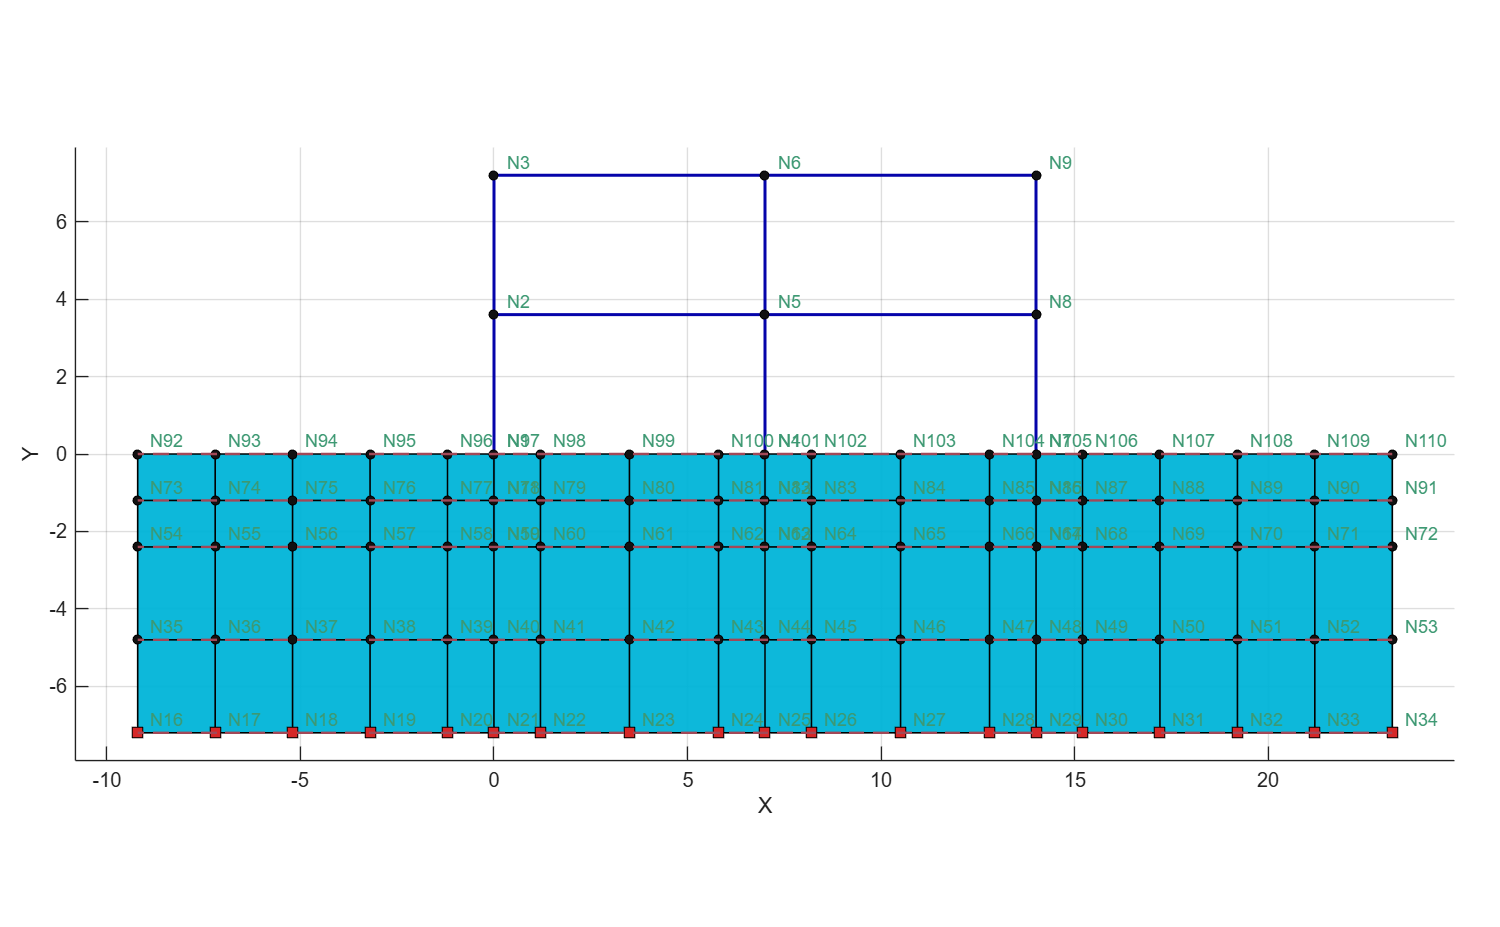

opts = opsm.vis.defaultPlotModelOptions;
opts.nodes.showLabels = true;

opsm.vis.plotModel(opts=opts);

### Analysis

Create ODB object.

OpenSeesMatlab creates a **new recorder object** in C++ for post-processing data. Therefore, data is automatically recorded during subsequent analysis.

ODB = opsm.post.createODB("myODB", interpolateBeamDisp=11, flushEvery=20);   % ODB

Output file: .openseesmatlab.output\Responses-myODB.odb\output.h5


#### Gravity analysis

%% ------------------------------------------------------------------------
% Additional recorders
%% ------------------------------------------------------------------------
% nodeList = [6 5 4 13 12 99 80 61 42 23];
% for i = 1:numel(nodeList)
%     tag = nodeList(i);
%     ops.recorder('Node', '-file', sprintf('node%d.out', tag), ...
%         '-time', '-node', tag, '-dof', 1, 2, 'disp');
% end

% ops.recorder('Element', '-ele', 23, '-time', '-file', 'stress23.out', 'material', 2, 'stress');
% ops.recorder('Element', '-ele', 41, '-time', '-file', 'stress41.out', 'material', 2, 'stress');
% ops.recorder('Element', '-ele', 59, '-time', '-file', 'stress59.out', 'material', 2, 'stress');
% ops.recorder('Element', '-ele', 77, '-time', '-file', 'stress77.out', 'material', 2, 'stress');
% 
% ops.recorder('Element', '-ele', 37, '-time', '-file', 'stress37.out', 'material', 2, 'stress');
% ops.recorder('Element', '-ele', 37, '-time', '-file', 'strain37.out', 'material', 2, 'strain');

%% ------------------------------------------------------------------------
% Static analysis: gravity step
%% ------------------------------------------------------------------------
ops.constraints('Transformation');
ops.numberer('RCM');
ops.test('NormDispIncr', 1.0e-6, 25, 2);
ops.integrator('LoadControl', 1, 1, 1, 1);
ops.algorithm('Newton');
ops.system('BandGeneral');
ops.analysis('Static');

ops.analyze(3);   % Automatically write data to the ODB.

[OpenSees] CTestNormDispIncr::test() - iteration: 6 current Norm: 2.68477e-11 (max: 1e-06, Norm deltaR: 9.20992e-11)
[OpenSees] CTestNormDispIncr::test() - iteration: 1 current Norm: 1.48353e-16 (max: 1e-06, Norm deltaR: 7.82232e-11)
[OpenSees] CTestNormDispIncr::test() - iteration: 1 current Norm: 1.4717e-16 (max: 1e-06, Norm deltaR: 5.10942e-11)


fprintf('Soil gravity nonlinear analysis completed.\n');

Soil gravity nonlinear analysis completed.


#### Seismic analysis

[elcentro.txt](../utils/elcentro.txt)   


%% ------------------------------------------------------------------------
% Dynamic analysis
%% ------------------------------------------------------------------------
ops.wipeAnalysis();

ops.constraints('Transformation');
ops.test('NormDispIncr', 1.0e-6, 25, 0);
ops.algorithm('Newton');
ops.numberer('RCM');
ops.system('BandGeneral');
% beta = 0.55
% gamma = (0.55 + 0.5)^2 / 4 = 0.275625
ops.integrator('Newmark', 0.55, 0.275625);
ops.analysis('Transient');


ops.timeSeries('Path', 1001, '-filePath', 'utils/elcentro.txt', '-dt', 0.01, '-factor', 3.0);
ops.pattern('UniformExcitation', 1, 1, '-accel', 1001);

tic;
ops.analyze(2400, 0.005);  % Automatically write data to the ODB.

ODB.close();  % stop to record

elapsedTime = toc;
fprintf('Completed time: %.6f seconds.\n', elapsedTime);

Completed time: 23.501424 seconds.


### Post-processing

#### Nodal responses

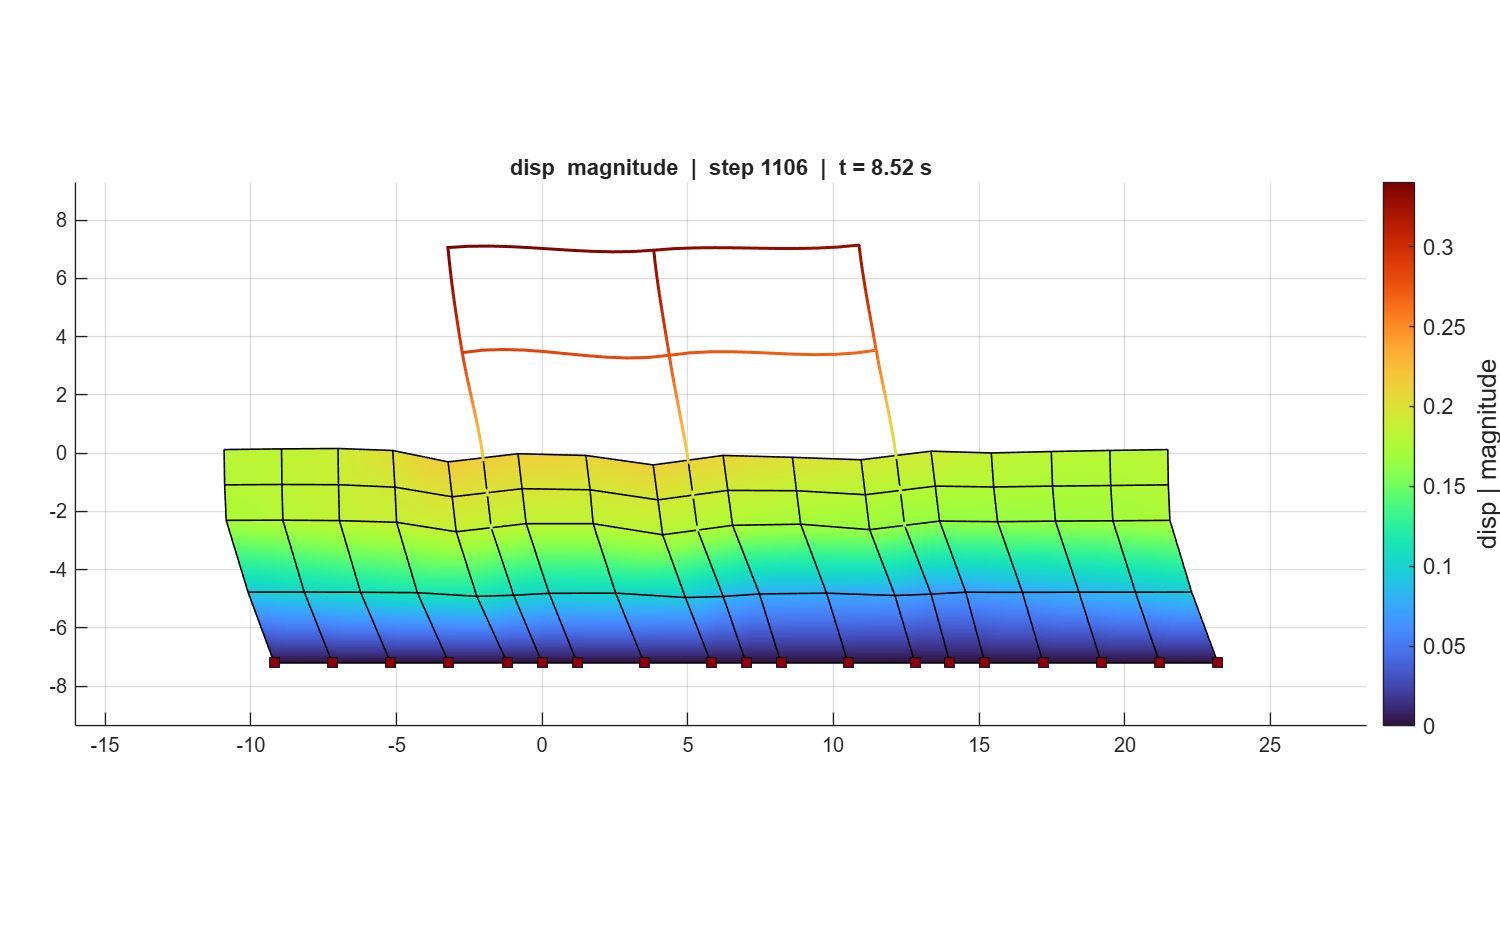

% 
nodeResp = opsm.post.getNodalResponse("myODB");
opsm.vis.plotNodalResponse(nodeResp, stepIdx="absMax");

### By paraview

If you want to demonstrate animations or other features in Paraview, run the following function.

opsm.post.writeResponsePVD("myODB");

nodal:         2403 steps -> paraview_output/pv_nodal/pv_nodal.pvd
plane:         2403 steps -> paraview_output/pv_plane/pv_plane.pvd
interp:        2403 steps -> paraview_output/pv_interp/pv_interp.pvd


If you want to display the deformation, please add the ``filter - common - wrap by vector``.  Select the ``disp`` and set the ``scaling factor``.

Note that when you set variables to display colors, you need to rescale the color bar range to cover the current time step or all time steps.

![](../utils/paraview-soil-structure.png)

If you want to display a vector graphic, please click ``filter - common - Calculator - disp/vel/accel...``, and on  Calculator to ``filter - common - Glyph - disp/vel/accel...`

![](../utils/paraview-soil-structure-vector.png)

#### Element responses

frameResp = opsm.post.getElementResponse("myODB", eleType="Frame");

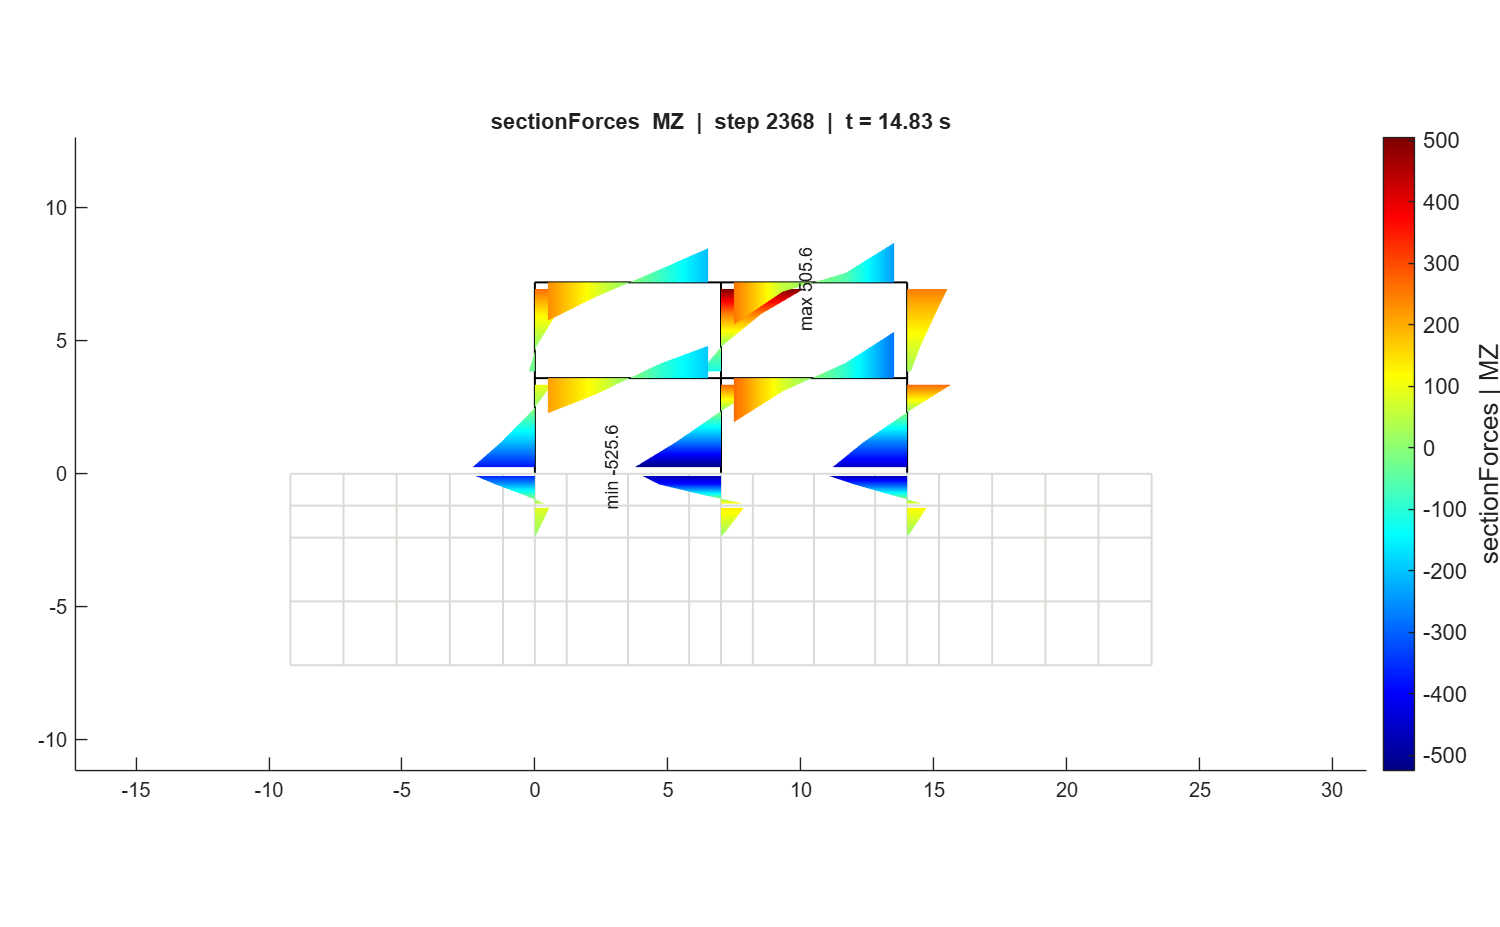

opsm.vis.plotFrameResponse(frameResp, stepIdx="absMax", respType="sectionForces", respComponent="MZ");
grid off;

planeResp = opsm.post.getElementResponse("myODB", eleType="Plane");

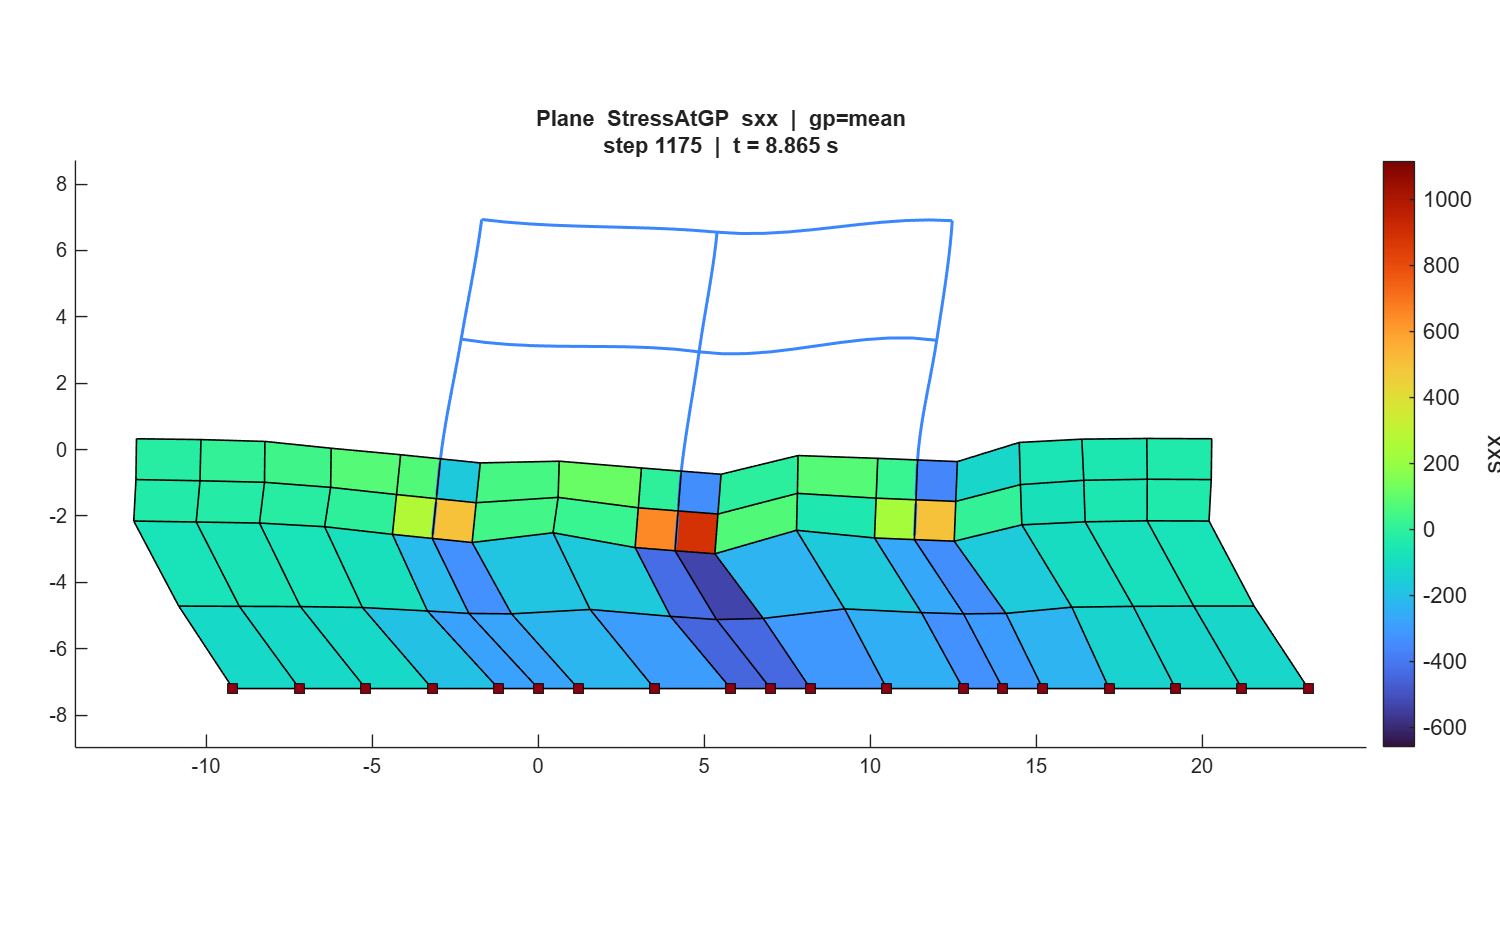

opsm.vis.plotContinuumResponse(planeResp, ...
    respType="StressAtGP", respComponent="sxx");
grid off

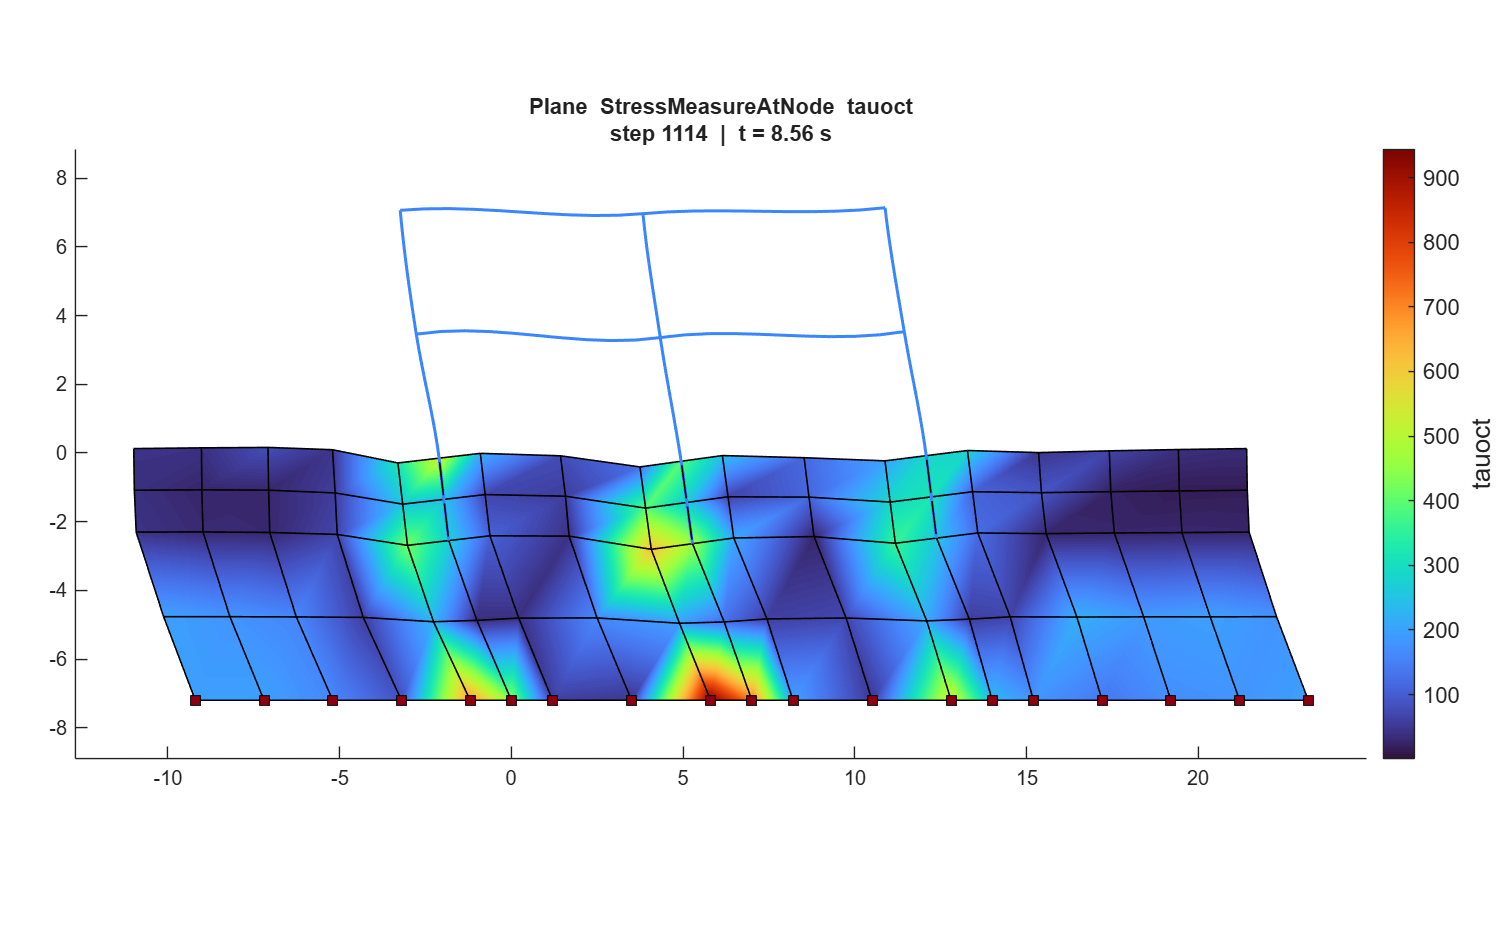

opsm.vis.plotContinuumResponse(planeResp, ...
    respType="StressMeasureAtNode", respComponent="tauOct");
grid off